ys = randn(1,10)

ys =    -0.1952   -0.2176   -0.3031    0.0230    0.0513    0.8261    1.5270    0.4669   -0.2097    0.6252


threshold = 0.2

threshold = 0.2000

i = 1;
for i = 1:10
    in = ys(i);
	out = distinguish(in, threshold);
    disp(['out: ', num2str(out), ' in:', num2str(in)])
    disp(['tan(v/2):', num2str(tanh2(in))])
end

out: 0 in:-0.19522


tan(v/2):-0.097302


out: 0 in:-0.21761


tan(v/2):-0.10838


out: 0 in:-0.30311


tan(v/2):-0.1504


out: 0 in:0.023046


tan(v/2):0.011522


out: 0 in:0.05129


tan(v/2):0.02564


out: 1 in:0.82606


tan(v/2):0.39104


out: 1 in:1.527


tan(v/2):0.64313


out: 1 in:0.46691


tan(v/2):0.22931


out: 0 in:-0.20971


tan(v/2):-0.10447


out: 1 in:0.62519


tan(v/2):0.3028


% 测试结束23333

## Draw the hyper plane

以平面为例（主要是高纬度不会），绘制超平面。

下图中，红绿交线即为本测试下的“超平面”

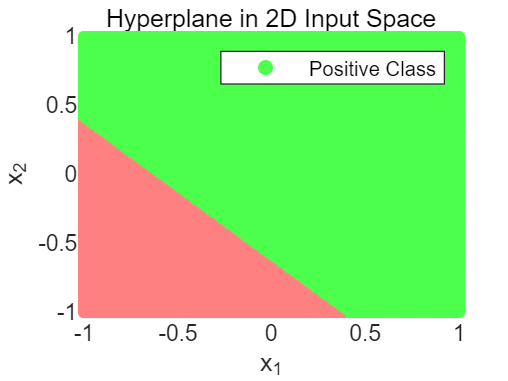

% 生成稠密的数据点
num_points = 233;
x1 = linspace(-1, 1, num_points);
x2 = linspace(-1, 1, num_points);
[X1, X2] = meshgrid(x1, x2);
input = [X1(:) X2(:)];

% 对每个数据点进行分类
% 假定w=[1 1 1]， threshold=0.5
output = zeros(size(X1));
for i = 1:size(X1, 1)
    for j = 1:size(X1, 2)
        output(i, j) = distinguish(X1(i, j)+X2(i, j)+1, threshold);
    end
end

% 将输出矩阵转换为向量
output_vector = reshape(output, [], 1);

% 根据分类结果生成颜色矩阵，用颜色来区分。
colors = zeros(num_points^2, 3);
for i = 1:length(output_vector)
    if output_vector(i) == 1 % 正类
        colors(i, :) = [0.3 1 0.3]; % 浅浅的绿色
    else % 负类
        colors(i, :) = [1 0.5 0.5]; % 更浅一点的红色
    end
end

% 绘制超平面
figure;
scatter(input(:,1), input(:,2), 20, colors, 'filled');
hold on;

% 调整坐标轴，-1~1范围。
axis([-1 1 -1 1]);

% 添加标题和标签
title('Hyperplane in 2D Input Space');
xlabel('x_1');
ylabel('x_2');

% 标记正类和负类
legend('Positive Class', 'Negative Class');


% 显示图例
legend('show');



function phi = tanh2(input)
    x = input / 2;
    ex = exp(x);
    nex = exp(-x);
    phi = (ex - nex) / (ex + nex);
end

% Deprecated
function d_phi = d_tanh2(input)
    var = tanh2(input);
    d_phi = 1 - var^2; % corrected formula for the derivative of tanh
end

function out = distinguish(y, threshold)
    var = tanh2(y);
    out = 0;
    if var > threshold
        out = 1;
    end
end
